# Bootcamp Day 2 Part 2

restoredefaultpath
addpath('/usr/local/MATLAB/toolboxes/fieldtrip/')
ft_defaults
addpath(genpath('/usr/local/MATLAB/toolboxes/hcn_toolbox/'))
addpath(genpath('/usr/local/MATLAB/toolboxes/fieldtrip/FieldtripBootcamp/'))

%%%% L4 - Anatomical reconstruction of intracranial data

## H3 - Analysis of human ECoG and SEEG

## Neurophysiology of cognition

Robert Knight

High frequency band = multi-units (infragranular layer) + calcium dendritic spikes (supragranular layer)

Intracranial eeg and behavior

## HFB tracks behavior

BOLD activity tightly coupled with HFB activity

Reliable at the single-trial level, critical for BCI

- tracks speech generation in AC, Broca, motor cortex at different times during the articulation process

- tracks load dependent working memory activation in frontal cortex

- PCF-Motor interaction (point of divergence between activity in preparatory and response channels) predicts behavior

## Long-range coherence selects networks

coherence between brain areas (small relative phase difference = increased communication [single unit activity]) and vice versa

theta-HFB coupling in humans (theta phase correlates with HFB power)

Johnson et al (Curr Biol 2017) (PLoS Biol 2018) - oscillatory coherence among different brain regions correlates with different aspects of task control & performance

hippocampal theta and HFB seems to increase activity (and is involved in determining contextual information in speech)

HFB activity during pre-play (before context is given) predicts RT after context completion

HFB in IPS shows increases in ipsilateral attention and even larger increases during contralteral attention

coherence between parietal and frontal electrodes significantly increases when you attend contralaterally (same with phase-amplitude coupling)

attention levels seem to fluctuate at 4-5 Hz (hit rate is cyclical, correlates with theta-band activity)

## Phase-amplitude coupling tunes local and distant processing

directional phase-amplitude coupling -> PFC theta drives motor cortex HFB

emotion - during fearful stimuli, amygdalar theta phase drives hippocampal HFB

choice and regret signals in OFC -> HFB activity explains variability in regret when you make a wrong bet in betting task

aging uncouples slow waves and spindles impairing memory

%%%% L6 - Connectivity analysis

## H4 - Coherence analysis

Measures of connectivity

- effective connectivity (causal) vs. functional (correlational)

- model based vs. data driven

- time domain vs. frequency domain

- nonlinear vs. linear

Many measures of frequency domain connectivity

Coherence analysis - looking at consistency of phase difference between signals

- high synchrony = small phase differences

Coherence is affected by both phase consistency and amplitude consistency

- coherency incldes both magnitude of coherence and angle of phase difference

PLV is sensitive only to phase consistency

coherence coefficent ~ cross-correlation coefficient

coherence^2 ~ % explained variance

coherecne coefficient similar to frequency domain regression

Slope of relative phase spectrum indicates the temporal precedence (~ directed influence)

- slope is often hard to estimate or close to 0

Granger causality

- Univariate Autoregressive models: linear regression on how well a signal can be reproduced based on shifted versions of the original signal (missing last n values)

- Bivariate autoregressive models: linear regression can signal X can be explained by its past and the past of signal Y, vice versa for signal Y

- Granger analysis is analogous to GLM models

Interpretational issues

- many connectivity metrics are biased

- bias often sample size dependent

- common pick up/field spread (other sources in brain, other physiological sources, especially problematic if those sources have some "internal synchronization" themselves)

- differences in signal (or noise) between experimental conditions (better SNR -> more reliable estimate of phase; more reliable phase -> more consistent phase difference)

Power and phase are confounded

- Fourier phase estimates depend on S/N ratio (more power -> more accurate phase estimate; better phase estimates -> higher connectivity)

Front Syst Neuro 2016 Bastos & Schoffelen; Schoffelen & Gross 2009 Hum Brain Map

## H4 - Analysis of corticomuscular coherence

To study the oscillatory synchrony between two signals, one can compute  the coherence. This is computed in the frequency domain by normalizing  the magnitude of the summed cross-spectral density between two signals  by their respective power. For each frequency bin the coherence value is a number between 0 and 1. The coherence values reflect the consistency  of the phase difference between the two signals at a given frequency. In this session we will explore the concept of coherence by investigating a dataset from an experiment in which the subject was required to  maintain an isometric contraction of a forearm muscle. The coherence  between the MEG signals and the acquired EMG will be estimated. First we will explore the coherence between the EMG signal and all MEG channels. Secondly, we will investigate how the coherence estimate is influenced  by the number of trials, and by the degree of spectral smoothing using  multitaper spectral analysis. Even though the example in this session  covers cortico-muscular coherence, coherence between sensors can be  calculated in exactly the same way.

## Preprocessing

We will calculate the coherence between the MEG and the EMG when the  subject extended her LEFT wrist, while keeping the right forearm muscle  relaxed. The first step is to read the data. In this section we will apply  automatic artifact rejection. Preprocessing requires the original MEG  dataset, which is available from [ftp://ftp.fieldtriptoolbox.org/pub/fieldtrip/tutorial/SubjectCMC.zip](ftp://ftp.fieldtriptoolbox.org/pub/fieldtrip/tutorial/SubjectCMC.zip).

The epochs of interest have to be defined according to a  custom-written function called trialfun_left.m. Note that this function  is not part of the FieldTrip toolbox: see [appendix 2](http://www.fieldtriptoolbox.org/tutorial/coherence#appendix_2trialfun_left), or download it from [ftp://ftp.fieldtriptoolbox.org/pub/fieldtrip/tutorial/coherence/trialfun_left.m](ftp://ftp.fieldtriptoolbox.org/pub/fieldtrip/tutorial/coherence/trialfun_left.m). This function uses the information provided by the triggers which were  recorded simultaneously with the data. In this experiment each trigger  corresponds with the start or the end of a contraction. The epochs which correspond to a contraction of the left forearm muscle are selected.  Subsequently these 10-second pieces are cut into ten 1-second epochs.

% find the interesting epochs of data
cfg = [];
cfg.trialfun                  = 'trialfun_left';
cfg.dataset                   = 'Fieldtrip/SubjectCMC/SubjectCMC.ds';
cfg = ft_definetrial(cfg);

evaluating trialfunction 'trialfun_left'


found 0 events
created 192 trials
the call to "ft_definetrial" took 4 seconds and required the additional allocation of an estimated 4 MB



% detect EOG artifacts in the MEG data
cfg.continuous                = 'yes';
cfg.artfctdef.eog.padding     = 0;
cfg.artfctdef.eog.bpfilter    = 'no';
cfg.artfctdef.eog.detrend     = 'yes';
cfg.artfctdef.eog.hilbert     = 'no';
cfg.artfctdef.eog.rectify     = 'yes';
cfg.artfctdef.eog.cutoff      = 2.5;
cfg.artfctdef.eog.interactive = 'no';
cfg = ft_artifact_eog(cfg);

 In ft_checkconfig at line 128
 In ft_artifact_eog at line 117

searching for artifacts in 1 channels
searching in trial 192 from 192

detected 9 artifacts
the call to "ft_artifact_zvalue" took 7 seconds and required the additional allocation of an estimated 2 MB



% detect jump artifacts in the MEG data
cfg.artfctdef.jump.interactive = 'no';
cfg.padding                    = 5;
cfg = ft_artifact_jump(cfg);

searching for artifacts in 151 channels
searching in trial 192 from 192



detected 0 artifacts
the call to "ft_artifact_zvalue" took 54 seconds and required the additional allocation of an estimated 1529 MB



% detect muscle artifacts in the MEG data
cfg.artfctdef.muscle.cutoff      = 8;
cfg.artfctdef.muscle.interactive = 'no';
cfg = ft_artifact_muscle(cfg);

searching for artifacts in 151 channels
searching in trial 192 from 192



detected 1 artifacts
the call to "ft_artifact_zvalue" took 30 seconds and required the additional allocation of an estimated 1549 MB



% reject the epochs that contain artifacts
cfg.artfctdef.reject          = 'complete';
cfg = ft_rejectartifact(cfg);

detected   9 eog artifacts
detected   0 jump artifacts
detected   1 muscle artifacts
rejected    9 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
filled parts of    0 trials with the specified value
resulting 183 trials
the call to "ft_rejectartifact" took 2 seconds and required the additional allocation of an estimated 194 MB



% preprocess the MEG data
cfg.demean                    = 'yes';
cfg.dftfilter                 = 'yes';
cfg.channel                   = {'MEG'};
cfg.continuous                = 'yes';
meg = ft_preprocessing(cfg);

processing channel { 'MLC11' 'MLC12' 'MLC13' 'MLC14' 'MLC15' 'MLC21' 'MLC22' 'MLC23' 'MLC24' 'MLC31' 'MLC32' 'MLC33' 'MLC41' 'MLC42' 'MLC43' 'MLF11' 'MLF12' 'MLF21' 'MLF22' 'MLF23' 'MLF31' 'MLF32' 'MLF33' 'MLF34' 'MLF41' 'MLF42' 'MLF43' 'MLF44' 'MLF45' 'MLF51' 'MLF52' 'MLO11' 'MLO12' 'MLO21' 'MLO22' 'MLO31' 'MLO32' 'MLO33' 'MLO41' 'MLO42' 'MLO43' 'MLP11' 'MLP12' 'MLP13' 'MLP21' 'MLP22' 'MLP31' 'MLP32' 'MLP33' 'MLP34' 'MLT11' 'MLT12' 'MLT13' 'MLT14' 'MLT15' 'MLT16' 'MLT21' 'MLT22' 'MLT23' 'MLT24' 'MLT25' 'MLT26' 'MLT31' 'MLT32' 'MLT33' 'MLT34' 'MLT35' 'MLT41' 'MLT42' 'MLT43' 'MLT44' 'MRC11' 'MRC12' 'MRC13' 'MRC14' 'MRC15' 'MRC21' 'MRC22' 'MRC23' 'MRC24' 'MRC31' 'MRC32' 'MRC33' 'MRC41' 'MRC42' 'MRC43' 'MRF11' 'MRF12' 'MRF21' 'MRF22' 'MRF23' 'MRF31' 'MRF32' 'MRF33' 'MRF34' 'MRF41' 'MRF42' 'MRF43' 'MRF44' 'MRF45' 'MRF51' 'MRF52' 'MRO11' 'MRO12' 'MRO21' 'MRO22' 'MRO31' 'MRO32' 'MRO33' 'MRO41' 'MRO42' 'MRO43' 'MRP11' 'MRP12' 'MRP13' 'MRP21' 'MRP22' 'MRP31' 'MRP32' 'MRP33' 'MRP34' 'MRT11' 'MR

Next, read the left and right EMG data. Note that the settings are  different for the EMG and MEG data. Most importantly, the EMG data are  highpass filtered and rectified. This is a standard procedure when  calculating cortico-muscle coherence.

cfg              = [];
cfg.dataset      = meg.cfg.dataset;
cfg.trl          = meg.cfg.trl;
cfg.continuous   = 'yes';
cfg.demean       = 'yes';
cfg.dftfilter    = 'yes';
cfg.channel      = {'EMGlft' 'EMGrgt'};
cfg.hpfilter     = 'yes';
cfg.hpfreq       = 10;
cfg.rectify      = 'yes';
emg = ft_preprocessing(cfg);

processing channel { 'EMGlft' 'EMGrgt' }
reading and preprocessing
reading and preprocessing trial 183 from 183

the call to "ft_preprocessing" took 9 seconds and required the additional allocation of an estimated 2 MB


- Finally, combine the EMG and MEG trials to a common data structure:

data = ft_appenddata([], meg, emg);

concatenating over the "chan" dimension
the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_appenddata" took 2 seconds and required the additional allocation of an estimated 253 MB


- Note, that due to the artifact rejection, this procedure is very slow  and we typically would want to perform this step only once. Therefore  you can save the preprocessed data

save data data
load data

- To get a feel for the data, plot a trial from a sensor overlying the  left motor-cortex (MRC21) and the left and right EMG-signals, by  selecting the first trial from the data:

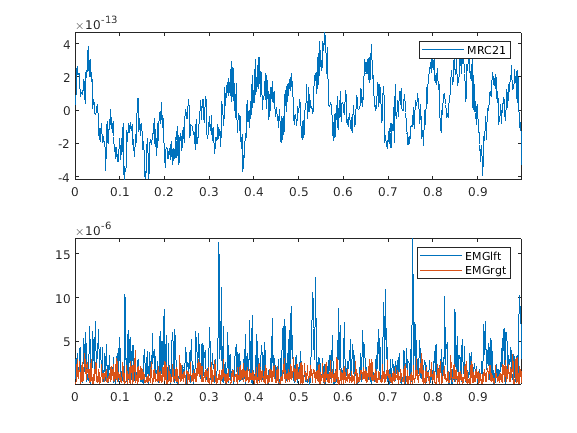

figure
subplot(2,1,1);
plot(data.time{1},data.trial{1}(77,:));
axis tight;
legend(data.label(77));

subplot(2,1,2);
plot(data.time{1},data.trial{1}(152:153,:));
axis tight;
legend(data.label(152:153));

## Computing the coherence

Using [**ft_freqanalysis**](http://www.fieldtriptoolbox.org/reference/ft_freqanalysis), the characteristics in the frequency domain will be computed. This step requires the preprocessed MEG and EMG data (see above or download from [ftp://ftp.fieldtriptoolbox.org/pub/fieldtrip/tutorial/coherence/data.mat](ftp://ftp.fieldtriptoolbox.org/pub/fieldtrip/tutorial/coherence/data.mat)). Load the data with:

After the computation of the frequency domain representation [**ft_connectivityanalysis**](http://www.fieldtriptoolbox.org/reference/ft_connectivityanalysis) will be used to compute the coherence. There are essentially two ways  of achieving the same coherence, and these will be explained below. The  main difference is the way in which the frequency domain representation  is computed. You can also check out [the different ways of representing frequency domain data](http://www.fieldtriptoolbox.org/faq/in_what_way_can_frequency_domain_data_be_represented_in_fieldtrip)

## Method 1

In this ‘method’ we will use [**ft_freqanalysis**](http://www.fieldtriptoolbox.org/reference/ft_freqanalysis) for the computation of the fourier spectra, which is the ‘bare’  frequency domain representation of the signal, where both amplitude and  phase information of the oscillations are represented in a complex  number for each frequency.

First, a configuration structure (cfg) must be defined. The  FFT-algorithm will be used to compute the Fourier representation of each signal. To optimize the estimation, spectral smoothing using  ‘multitapers’ will be applied. In this context, the degree of  ‘smoothing’ (as defined in the parameter cfg.tapsmofrq) is critical. We  will return to this parameter later.

cfg            = [];
cfg.output     = 'fourier';
cfg.method     = 'mtmfft';
cfg.foilim     = [5 100];
cfg.tapsmofrq  = 5;
cfg.keeptrials = 'yes';
cfg.channel    = {'MEG' 'EMGlft' 'EMGrgt'};
freqfourier    = ft_freqanalysis(cfg, data);

the input is raw data with 153 channels and 183 trials
the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 1 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 183/183 nfft: 1200 samples, datalength: 1200 samples, 9 tapers

the call to "ft_freqanalysis" took 12 seconds and required the additional allocation of an estimated 374 MB


## Method 2

In this ‘method’ we will use [**ft_freqanalysis**](http://www.fieldtriptoolbox.org/reference/ft_freqanalysis) for the computation of the cross- and power spectra, which are  mathematically constructed from the multiplication of a complex-valued  fourier spectrum with the complex conjugate of another fourier spectrum. If the two fourier spectra are derived from the same channel, the cross spectrum is called the auto spectrum, and this is exactly the same as  the power spectrum. Rather than in method 1 (see above), where the phase in the fourier spectra represented the *phase* of the oscillation, the phase in the cross spectra represent the *phase difference* between the oscillations of a specific channel pair. For this reason,  we need to specify in the cfg between which pairs we want to compute the cross spectra.

cfg            = [];
cfg.output     = 'powandcsd';
cfg.method     = 'mtmfft';
cfg.foilim     = [5 100];
cfg.tapsmofrq  = 5;
cfg.keeptrials = 'yes';
cfg.channel    = {'MEG' 'EMGlft' 'EMGrgt'};
cfg.channelcmb = {'MEG' 'EMGlft'; 'MEG' 'EMGrgt'};
freq           = ft_freqanalysis(cfg, data);

the input is raw data with 153 channels and 183 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 183/183 nfft: 1200 samples, datalength: 1200 samples, 9 tapers

the call to "ft_freqanalysis" took 8 seconds and required the additional allocation of an estimated 83 MB


To calculate the coherence between the EMG and the MEG signals from the  fourier spectra, or from the power- and cross spectra use the following  function. This function does not care whether the input data contains  fourier spectra, or power/cross spectra.

cfg            = [];
cfg.method     = 'coh';
cfg.channelcmb = {'MEG' 'EMG'};
fd             = ft_connectivityanalysis(cfg, freq);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 82 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_connectivityanalysis" took 2 seconds and required the additional allocation of an estimated 124 MB


fdfourier      = ft_connectivityanalysis(cfg, freqfourier);

the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 369 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_connectivityanalysis" took 6 seconds and required the additional allocation of an estimated 369 MB


The field fd.cohspctrm/fdfourier.cohspctrm now contains the coherence for all MEG sensors with respect to the EMG signals.

## Displaying the coherence

Visualize the coherence between the EMG and all the MEG sensor

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
selected 151 channels for cohspctrm


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 1 seconds and required the additional allocation of an estimated 0 MB


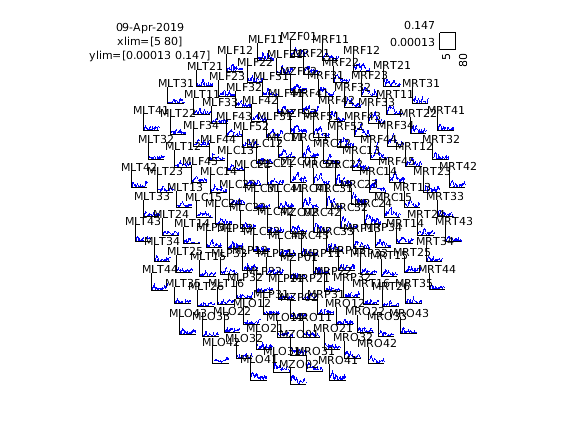

the call to "ft_multiplotER" took 4 seconds and required the additional allocation of an estimated 2 MB


ans = struct with fields:
            parameter: 'cohspctrm'
                 xlim: [5 80]
               layout: 'CTF151_helmet.mat'
           showlabels: 'yes'
          trackconfig: 'off'
          checkconfig: 'loose'
            checkpath: 'pedantic'
            checksize: 100000
         showcallinfo: 'yes'
                debug: 'no'
    outputfilepresent: 'overwrite'
        trackcallinfo: 'yes'
        trackdatainfo: 'no'
              toolbox: [1×1 struct]
         notification: [1×1 struct]
           trackusage: '6D39287C'
             progress: [1×1 struct]
             callinfo: [1×1 struct]
              version: [1×1 struct]
             baseline: 'no'
               trials: 'all'
                 ylim: 'maxmin'
              comment: '09-Apr-2019'
            limittext: 'default'
                 axes: 'yes'
          showoutline: 'no'
            showscale: 'yes'
          showcomment: 'yes'
                  box: 'no'
             fontsize: 8
           fontweight: 

cfg                  = [];
cfg.parameter        = 'cohspctrm';
cfg.xlim             = [5 80];
cfg.refchannel       = 'EMGlft';
cfg.layout           = 'CTF151_helmet.mat';
cfg.showlabels       = 'yes';
figure; ft_multiplotER(cfg, fd)

Plot the coherence for sensor MRC21 (using the same settings as in [**ft_multiplotER**](http://www.fieldtriptoolbox.org/reference/ft_multiplotER)

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
selected 151 channels for cohspctrm


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


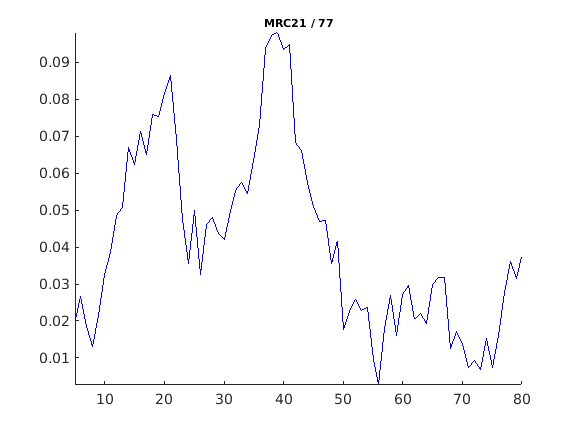

the call to "ft_singleplotER" took 1 seconds and required the additional allocation of an estimated 0 MB


cfg.channel = 'MRC21';
figure; ft_singleplotER(cfg, fd);

Plot a topographical distribution of the coherence in the beta band. The variable cfg.xlim defines the edges of the frequency band.

reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 1 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
selected 151 channels for cohspctrm


the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


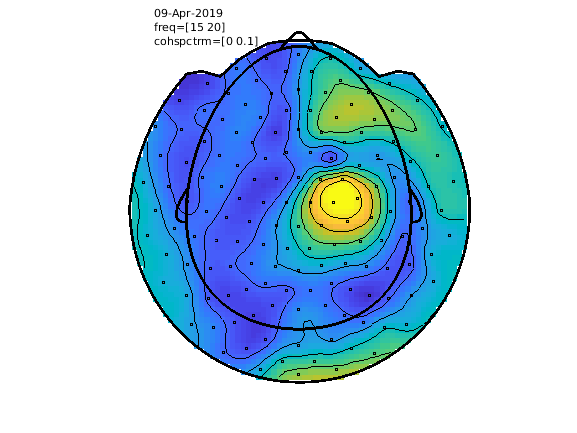

the call to "ft_topoplotER" took 2 seconds and required the additional allocation of an estimated 4 MB
the call to "ft_topoplotER" took 4 seconds and required the additional allocation of an estimated 5 MB


cfg                  = [];
cfg.parameter        = 'cohspctrm';
cfg.xlim             = [15 20];
cfg.zlim             = [0 0.1];
cfg.refchannel       = 'EMGlft';
cfg.layout           = 'CTF151_helmet.mat';
figure; ft_topoplotER(cfg, fd)


% not sure why image of head is not stretched to be same shape as
% topgraphic plot of coherence

Plot the topographic representation for other frequencies that might be of interest.

reading layout from file CTF151_helmet.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
selected 151 channels for cohspctrm


the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


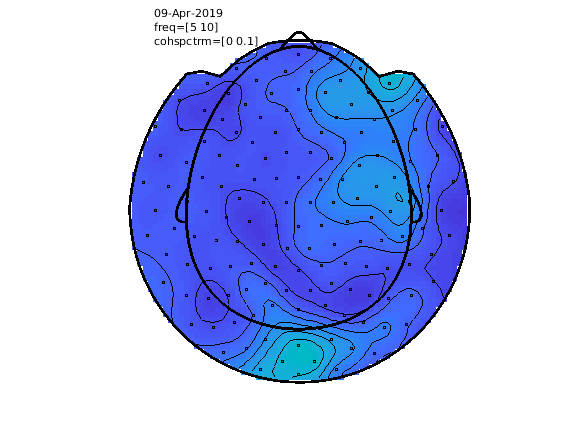

the call to "ft_topoplotER" took 2 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_topoplotER" took 3 seconds and required the additional allocation of an estimated 1 MB


cfg                  = [];
cfg.parameter        = 'cohspctrm';
cfg.xlim             = [3 10];
cfg.zlim             = [0 0.1];
cfg.refchannel       = 'EMGlft';
cfg.layout           = 'CTF151_helmet.mat';
figure; ft_topoplotER(cfg, fd)

Explore the consequence of changing the smoothing in the frequency  domain. Do this by recomputing the cortico-muscular coherence between  the EMG signal and MEG sensor MRC21 for different degrees of smoothing.  Compute the powerspectra and the cross-spectra, and the corresponding  coherence using different degrees of smoothing.

cfg            = [];
cfg.output     = 'powandcsd';
cfg.method     = 'mtmfft';
cfg.foilim     = [5 100];
cfg.tapsmofrq  = 2;
cfg.keeptrials = 'yes';
cfg.channel    = {'MEG' 'EMGlft'};
cfg.channelcmb = {'MEG' 'EMGlft'};
freq2          = ft_freqanalysis(cfg,data);

the input is raw data with 153 channels and 183 trials
the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 23 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 183/183 nfft: 1200 samples, datalength: 1200 samples, 3 tapers

the call to "ft_freqanalysis" took 5 seconds and required the additional allocation of an estimated 126 MB



cfg            = [];
cfg.method     = 'coh';
cfg.channelcmb = {'MEG' 'EMG'};
fd2            = ft_connectivityanalysis(cfg,freq2);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 41 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_connectivityanalysis" took 1 seconds and required the additional allocation of an estimated 82 MB


Plot the results of the 5 and 2Hz smoothing:

the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 1 MB
selected 151 channels for cohspctrm
selected 151 channels for cohspctrm


the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 1 MB


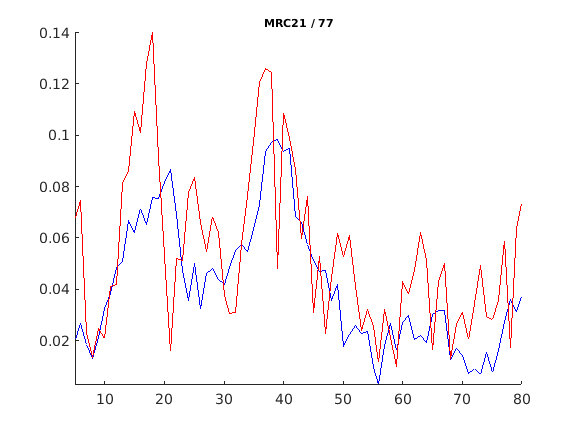

the call to "ft_singleplotER" took 1 seconds and required the additional allocation of an estimated 1 MB


cfg               = [];
cfg.parameter     = 'cohspctrm';
cfg.refchannel    = 'EMGlft';
cfg.xlim          = [5 80];
cfg.channel       = 'MRC21';
figure; ft_singleplotER(cfg, fd, fd2);

10 Hz smoothing (e.g. cfg.tapsmofrq = 10 Hz)

cfg            = [];
cfg.output     = 'powandcsd';
cfg.method     = 'mtmfft';
cfg.foilim     = [5 100];
cfg.keeptrials = 'yes';
cfg.channel    = {'MEG' 'EMGlft'};
cfg.channelcmb = {'MEG' 'EMGlft'};
cfg.tapsmofrq = 10;
freq10        = ft_freqanalysis(cfg,data);

the input is raw data with 153 channels and 183 trials
the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 0 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 183/183 nfft: 1200 samples, datalength: 1200 samples, 19 tapers

the call to "ft_freqanalysis" took 20 seconds and required the additional allocation of an estimated 94 MB



cfg            = [];
cfg.method     = 'coh';
cfg.channelcmb = {'MEG' 'EMG'};
fd10          = ft_connectivityanalysis(cfg,freq10);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 41 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_connectivityanalysis" took 2 seconds and required the additional allocation of an estimated 82 MB


Plot the results of the 5, 2, and 10 Hz smoothing:

the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 0 MB
selected 151 channels for cohspctrm
selected 151 channels for cohspctrm
selected 151 channels for cohspctrm


the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 0 MB


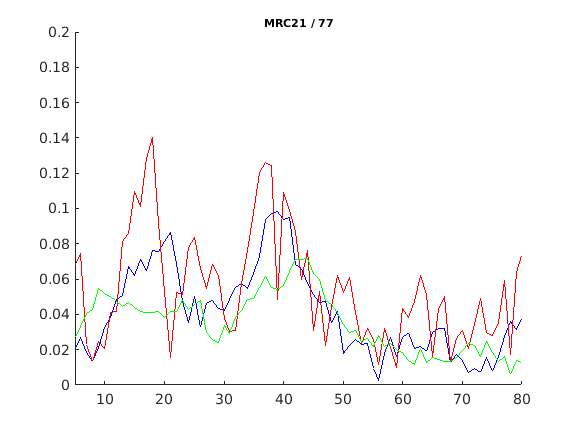

the call to "ft_singleplotER" took 2 seconds and required the additional allocation of an estimated 1 MB


cfg               = [];
cfg.parameter     = 'cohspctrm';
cfg.xlim          = [5 80];
cfg.ylim          = [0 0.2];
cfg.refchannel    = 'EMGlft';
cfg.channel       = 'MRC21';
figure;ft_singleplotER(cfg, fd, fd2, fd10);

Another question pertains to how the estimate of coherence is  affected by the number of trials. We will compare the cortico-muscular  coherence at two MEG sensors for different amount of data.  

Create the following configuration, and compute the coherence.

cfg            = [];
cfg.output     = 'powandcsd';
cfg.method     = 'mtmfft';
cfg.foilim     = [5 100];
cfg.tapsmofrq  = 5;
cfg.keeptrials = 'yes';
cfg.channel    = {'MEG' 'EMGlft'};
cfg.channelcmb = {'MEG' 'EMGlft'};
cfg.trials     = 1:50;
freq50         = ft_freqanalysis(cfg,data);

the input is raw data with 153 channels and 183 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 74 MB
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 50/50 nfft: 1200 samples, datalength: 1200 samples, 9 tapers

the call to "ft_freqanalysis" took 2 seconds and required the additional allocation of an estimated 74 MB



cfg            = [];
cfg.method     = 'coh';
cfg.channelcmb = {'MEG' 'EMG'};
fd50           = ft_connectivityanalysis(cfg,freq50);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_connectivityanalysis" took 2 seconds and required the additional allocation of an estimated 1 MB


the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 0 MB
selected 151 channels for cohspctrm
selected 151 channels for cohspctrm


the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 0 MB


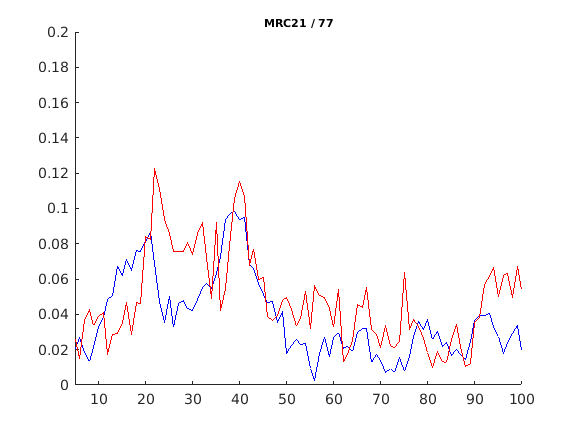

the call to "ft_singleplotER" took 1 seconds and required the additional allocation of an estimated 0 MB


ans = struct with fields:
            parameter: 'cohspctrm'
                 xlim: [5 100]
                 ylim: [0 0.2000]
              channel: {'MRC21'}
          trackconfig: 'off'
          checkconfig: 'loose'
            checkpath: 'pedantic'
            checksize: 100000
         showcallinfo: 'yes'
                debug: 'no'
    outputfilepresent: 'overwrite'
        trackcallinfo: 'yes'
        trackdatainfo: 'no'
              toolbox: [1×1 struct]
         notification: [1×1 struct]
           trackusage: '6D39287C'
             progress: [1×1 struct]
             callinfo: [1×1 struct]
              version: [1×1 struct]
             baseline: 'no'
               trials: 'all'
                 zlim: 'maxmin'
              comment: '09-Apr-2019\n'
                 axes: 'yes'
             fontsize: 8
           graphcolor: 'brgkywrgbkywrgbkywrgbkyw'
              hotkeys: 'yes'
          interactive: 'yes'
             renderer: []
        maskparameter: []
            


cfg                  = [];
cfg.parameter        = 'cohspctrm';
cfg.xlim             = [5 100];
cfg.ylim             = [0 0.2];
cfg.refchannel       = 'EMGlft';
cfg.channel          = 'MRC21';
figure; ft_singleplotER(cfg, fd, fd50)

## Non-parametric statistical metrics & clustering

Solutions to control the FWER

- Bonferroni correction

- False discovery rate

- Use a Monte Carlo approximation of the randomization distribution of the maximum statistic